%All constants
%(r>d)
sigma=0.1;
r=0.08;
d=0.03;
T=1;
E=25;
N=400;
K=400;
%From Wilmot's paper,generally X=4E
X=4*E;
q1=zeros(1,N+1);

delt=T/K;
h=X/(1+(sigma^2/(r-d))*(N-1));
x=[0,h*(1+(sigma^2/(r-d))*([1:N]-1))];
hv=x(2:end)-x(1:end-1);

q2=1-q1;
aminus=delt*q1(2:N).*(-sigma^2*x(1:N-1).^2+(r-d)*hv(1:N-1).*x(1:N-1))-delt*q2(2:N).*(sigma^2*x(2:N).^2+(r-d)*hv(1:N-1).*x(2:N))
aminus=aminus./((hv(1:N-1)+hv(2:N)).*hv(1:N-1));
aplus=aminus;
aminus=aminus+(q1(2:N).*(((r-d)*x(1:N-1)+hv(1:N-1)*r)*delt+hv(1:N-1))+delt*q2(2:N).*((r-d)*x(2:N)))./hv(1:N-1);
ac=1+r*delt-aminus-aplus;

V1=zeros(K+1,N+1);
for j=1:K+1
    for i=1:N+1
        V1(j,i)=euput(X*(i-1)/N,T*(j-1)/K,r,sigma,d,T,E);
    end
end

V2=zeros(K+1,N+1);
V2(:,1)=E*(1-exp(-r*(T-(T/K)*[0:K])));
A=diag(ac)+diag(aplus(1:N-2),1)+diag(aminus(1:N-2),-1);
for j=K:-1:1
    b=q1(1:N-1).*V2(j+1,1:N-1)+q2(1:N-1).*V2(j+1,2:N);
    b(1)=b(1)-aminus(1)*V2(j,1);
    b(N-1)=b(N-1)-aplus(N-1)*V2(j,N+1);
    V2(j,2:N)=A\b.';
    V2(j,1:N+1)=max(V2(j,1:N+1),max(E-[0:N]*X/N,0)-V1(j,1:N+1));
end

V=V2+V1;
[xm,tm]=meshgrid((X/N)*[0:N],(T/K)*[0:K]);
%surf(xm, tm,V , 'FaceColor', 'blue', 'EdgeColor', 'none');
plot((X/N)*[0:N],V(1,:),'r--')

%All constants
%(r>d)
sigma=0.4;
r=0.06;
d=0.02;
T=1;
E=25;
N=400;
K=400;
%From Wilmot's paper,generally X=4E
X=4*E;
q1=zeros(1,N+1);

delt=T/K;
h=X/(1+(sigma^2/(r-d))*(N-1));
x=[0,h*(1+(sigma^2/(r-d))*([1:N]-1))];
hv=x(2:end)-x(1:end-1);

q2=1-q1;
aminus=delt*q1(2:N).*(-sigma^2*x(1:N-1).^2+(r-d)*hv(1:N-1).*x(1:N-1))-delt*q2(2:N).*(sigma^2*x(2:N).^2+(r-d)*hv(1:N-1).*x(2:N))

aminus =    -0.0000   -0.0000   -0.0001   -0.0003   -0.0005   -0.0007   -0.0010   -0.0014   -0.0018   -0.0022   -0.0027   -0.0032   -0.0038   -0.0045   -0.0052   -0.0059   -0.0067   -0.0076   -0.0085   -0.0094   -0.0104   -0.0115   -0.0126   -0.0137   -0.0149   -0.0162   -0.0175   -0.0188   -0.0202   -0.0217   -0.0232   -0.0247   -0.0263   -0.0280   -0.0297   -0.0314   -0.0332   -0.0351   -0.0370   -0.0389   -0.0409   -0.0430   -0.0451   -0.0472   -0.0494   -0.0517   -0.0540   -0.0563   -0.0587   -0.0612


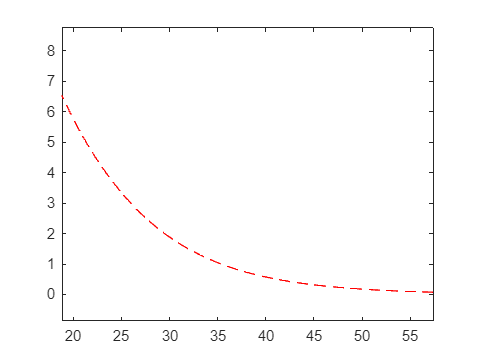

aminus=aminus./((hv(1:N-1)+hv(2:N)).*hv(1:N-1));
aplus=aminus;
aminus=aminus+(q1(2:N).*(((r-d)*x(1:N-1)+hv(1:N-1)*r)*delt+hv(1:N-1))+delt*q2(2:N).*((r-d)*x(2:N)))./hv(1:N-1);
ac=1+r*delt-aminus-aplus;

V1=zeros(K+1,N+1);
for j=1:K+1
    for i=1:N+1
        V1(j,i)=euput(X*(i-1)/N,T*(j-1)/K,r,sigma,d,T,E);
    end
end

V2=zeros(K+1,N+1);
V2(:,1)=E*(1-exp(-r*(T-(T/K)*[0:K])));
A=diag(ac)+diag(aplus(1:N-2),1)+diag(aminus(1:N-2),-1);
for j=K:-1:1
    b=q1(1:N-1).*V2(j+1,1:N-1)+q2(1:N-1).*V2(j+1,2:N);
    b(1)=b(1)-aminus(1)*V2(j,1);
    b(N-1)=b(N-1)-aplus(N-1)*V2(j,N+1);
    V2(j,2:N)=A\b.';
    V2(j,1:N+1)=max(V2(j,1:N+1),max(E-[0:N]*X/N,0)-V1(j,1:N+1));
end

V=V2+V1;
[xm,tm]=meshgrid((X/N)*[0:N],(T/K)*[0:K]);
%surf(xm, tm,V , 'FaceColor', 'blue', 'EdgeColor', 'none');
plot((X/N)*[0:N],V(1,:),'r--')

function result=euput(x,t,r,sigma,d,T,E)
    d1=(log(x/E)+(r-d+sigma^2/2)*(T-t))/(sigma*sqrt(T-t));
    d2=d1-sigma*sqrt(T-t);
    result=E*exp(-r*(T-t))*normcdf(-d2)-x*exp(-d*(T-t))*normcdf(-d1);
end